## Show that the oblique incidence case can be handled by the Lorentz boost method.

Proof:

 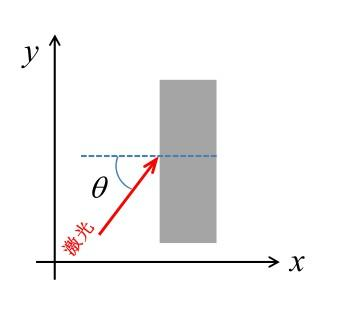

We can apply the Lorentz transform formula. After boost by $c\sin \theta$ in $y$  direction, the speed of light in the new reference frame is


$$v_y=\frac{c\sin\theta-c\sin\theta}{1-\beta\sin\theta}=0\\
v_x=\frac{\gamma c\cos\theta}{1-\beta\sin\theta}$$


where $\beta=\frac{c\sin\theta}{c}=\sin\theta$, then we can simplify the formulas (2) into


$$\gamma=\sqrt{1-\beta^2}=\cos \theta\\
v_x=c
$$


In other words, in the view of the observer in the new frame, the incidence EM wave is parallel to the $x'$ axis, and the speed of EM wave is still $c$.

Which is apparent since there's a basic principle that the speed of light should be conserved. Note that now the plasma are in motion, with velocity $v_y'=-c\sin\theta$.

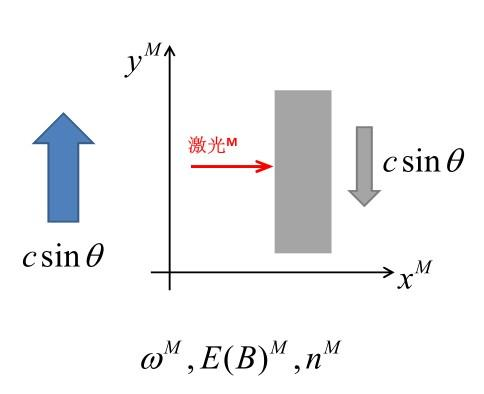

## Use the JPIC1d program to simulate the relativistic Doppler effect. Plot how the reflected wave frequency depends on the flying mirror's $\gamma$ factor, and compare the result with theoretical predictions.

% generate the files with gamma ranging from 1.5 to 5.0 and renamed in the
% postfix.
for i=1.5:0.1:5.0
    if exist(sprintf("./data/t_pl_pr_%.1f",i))~=0
        fprintf("skipped gamma="+i+'\n');
        continue;
    end
    setGammaInFile(i);
    !jpic.exe ./data/input.inp
    command=sprintf("!rename .\\data\\t_pl_pr t_pl_pr_%.1f",i)
    eval(command);
    !del .\data\input.lpi
end

skipped gamma=1.5
skipped gamma=1.6
skipped gamma=1.7
skipped gamma=1.8
skipped gamma=1.9
skipped gamma=2
skipped gamma=2.1
skipped gamma=2.2
skipped gamma=2.3
skipped gamma=2.4
skipped gamma=2.5
skipped gamma=2.6
skipped gamma=2.7
skipped gamma=2.8
skipped gamma=2.9
skipped gamma=3
skipped gamma=3.1
skipped gamma=3.2
skipped gamma=3.3
skipped gamma=3.4
skipped gamma=3.5
skipped gamma=3.6
skipped gamma=3.7
skipped gamma=3.8
skipped gamma=3.9
skipped gamma=4
skipped gamma=4.1
skipped gamma=4.2
skipped gamma=4.3
skipped gamma=4.4
skipped gamma=4.5
skipped gamma=4.6
skipped gamma=4.7
skipped gamma=4.8
skipped gamma=4.9
skipped gamma=5


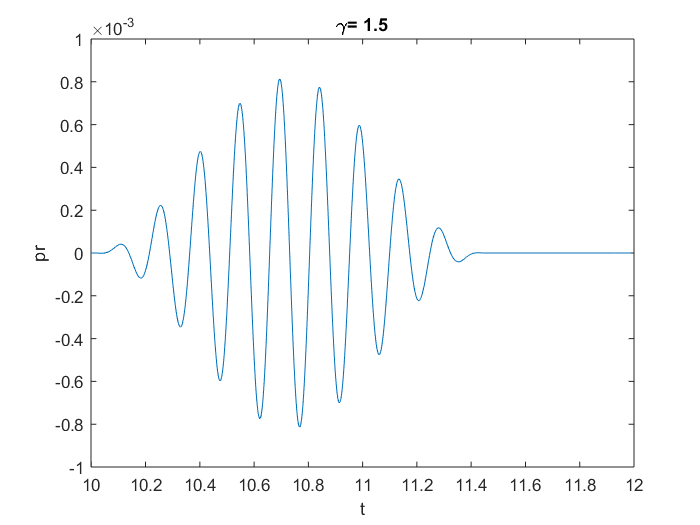

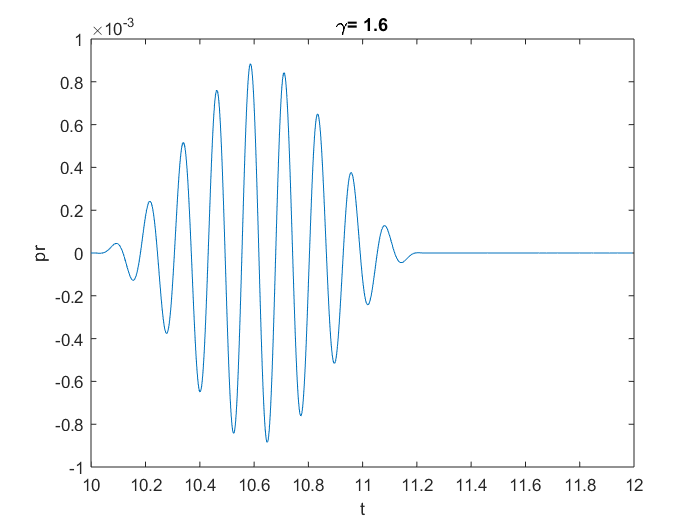

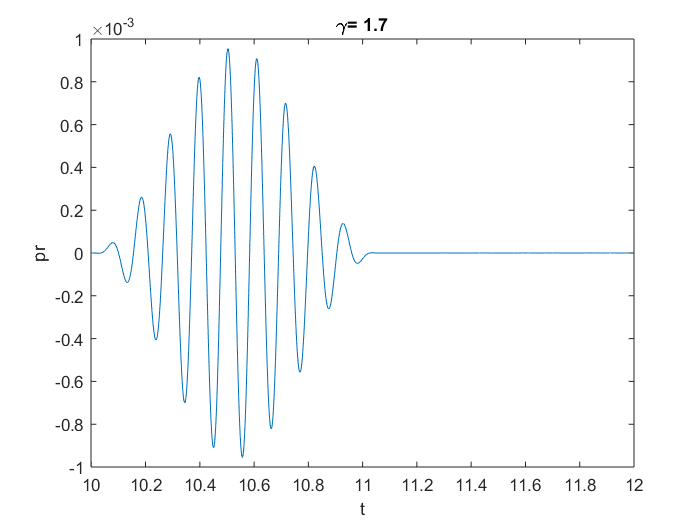

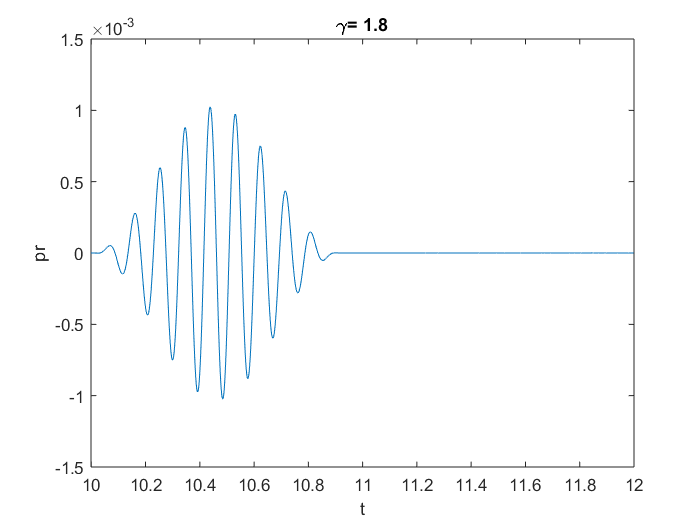

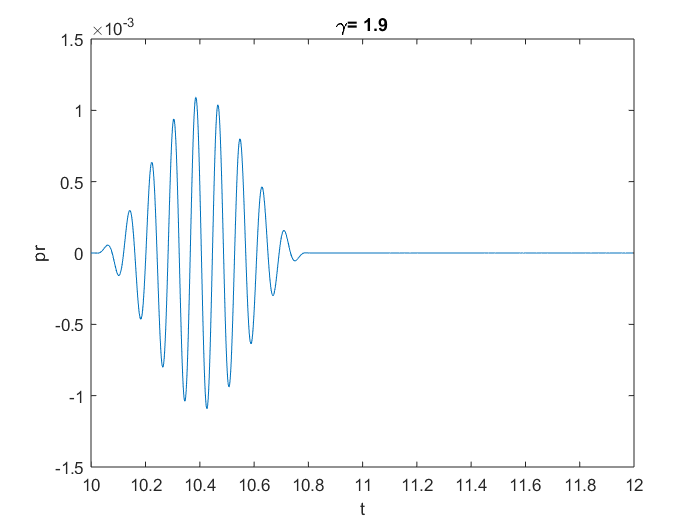

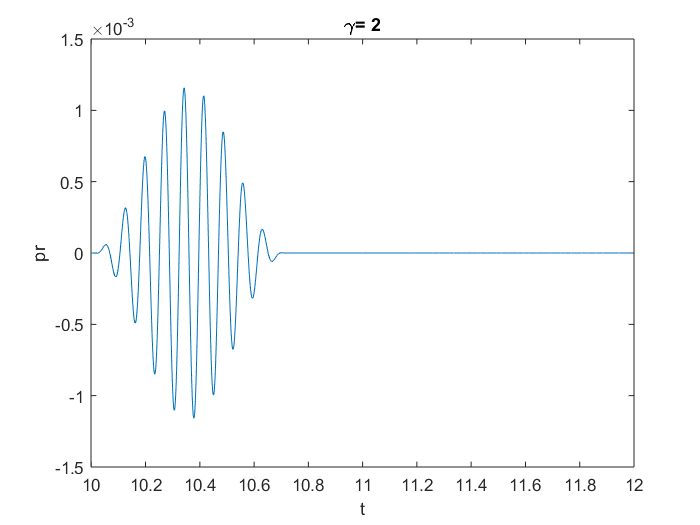

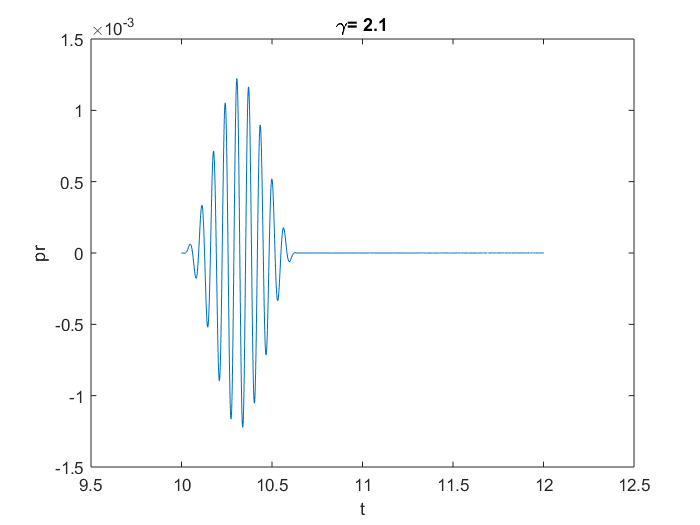

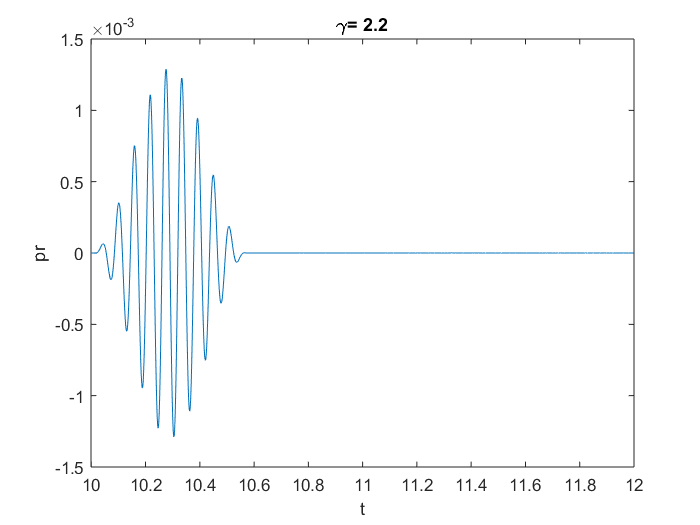

% check the waveform and extract the maximum frequency component
index=0;
f=zeros([1,36]);
for i1 = 1.5:0.1:5.0
    strloadX=sprintf("./data/t_pl_pr_%.1f",i1);
    s = load(strloadX);
    for i2=1:12002
        if s(i2,3)~=0
            break
        end
    end
    for j=12002:-1:1
        if s(j,3)~=0
            break
        end
    end
    N=j-i2+1;
    % only displays the part that the value is not zero.
    t=s(i2:j,1);
    pr=s(i2:j,3);
    figure;
    plot(t,pr);
    title("\gamma= "+i1);
    xlabel("t");
    ylabel("pr");
    fourier=fft(pr);
    Y=abs(fourier(1:floor(N/2)+1));
    % extract the greatest frequency component
    [m,I]=max(Y);
    index=index+1;
    f(index)=I*1000/N;
end

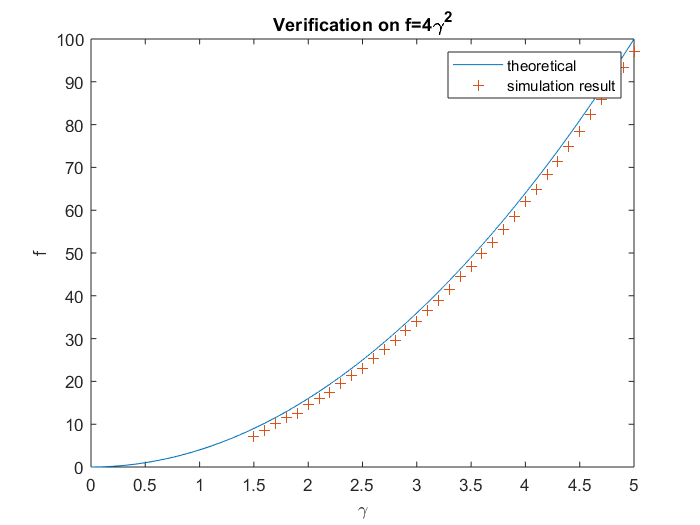

% plot the gamma dependence.
gamma0=0:0.1:5;
figure;
plot(gamma0,gamma0.^2*4,'DisplayName',"theoretical");
xlabel('\gamma');ylabel('f'); % parabolic theory
xlim([0,5]);
hold on
scatter(1.5:0.1:5.0,f,'+','DisplayName',"simulation result") % Simulation result
title("Verification on f=4\gamma^2");
legend;

The simulation result agrees well with the theoretical line, as we expected.

function [gamma]=setGammaInFile(setGamma)
% sets the gamma in file as setGamma's value, return the original gamma.
fileName="./data/input.inp";
fid=fopen(fileName,'r');
% first read 5 lines
lines={};
i=0;
expression="(?<=mirror_gamma *= *)[0-9.]+";
while ~feof(fid)
    i=i+1;
    lines{i}=fgets(fid);
    match=regexp(lines{i},expression);
    if ~isempty(match)
        subLine=lines{i}(match(1):end);
        % this line can read gamma, relatively robust
        gamma=sscanf(subLine,"%f");
        lines{i}=regexprep(lines{i},expression,sprintf("%.1f",setGamma));
    end
end
fclose(fid);
writeFile="./data/input.inp";
fid=fopen(writeFile,'w');
for i=1:length(lines)
    fprintf(fid,lines{i});
end
fclose(fid);
end
